## **Review Q1 - BVP**

I = 30000 * 10^-8;
E = 200 * 10^6;
w = 15;
L = 3;

x0 = 0;
xf = L;
y0 = 0;
yf = 0;

**Shooting Method**

dY = @(x, Y) [Y(2); ((w*L*x)/2 - (w*x^2)/2)/(E*I)];

g1 = 0;
[x1, y1] = ode45(dY, [x0, xf], [y0, g1]);
y1_end = y1(end, 1)

y1_end = 8.4375e-04

g2 = -.001;
[x2, y2] = ode45(dY, [x0, xf], [y0, g2]);
y2_end = y2(end, 1)

y2_end = -0.0022

gEx = g1 + (g2-g1)/(y2_end-y1_end)*(yf-y1_end)

gEx = -2.8125e-04

[x, y] = ode45(dY, [x0, xf], [y0, gEx]);
y_end = y(end, 1)

y_end = 0

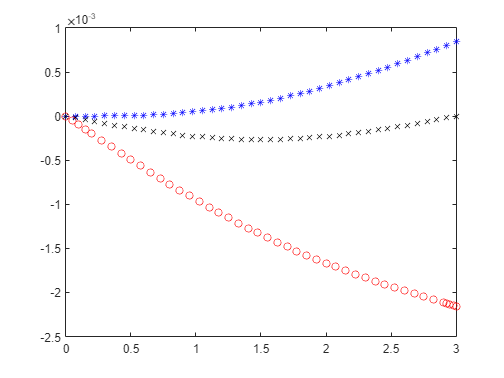

figure()
plot(x1, y1(:,1), "b*", x2, y2(:,1), "ro", x, y(:,1), "kx")

**Finite Difference**

dx = 0.6;

X_FDM = x0:dx:xf;
n = (xf-x0)/dx-1;

A = diag(-2*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1);
for i = 1:n
    b(i,1) = (w*dx^2)/(2*E*I)*(L*X_FDM(i+1)-X_FDM(i+1)^2);
    if i == 1
        b(i:1) = b(i:1) - y0;
    elseif i == n
        b(i:1) = b(i:1) - yf;
    end
end
A,b

A =     -2     1     0     0
     1    -2     1     0
     0     1    -2     1
     0     0     1    -2


b = 1.0e-04 *

    0.6480
    0.9720
    0.9720
    0.6480


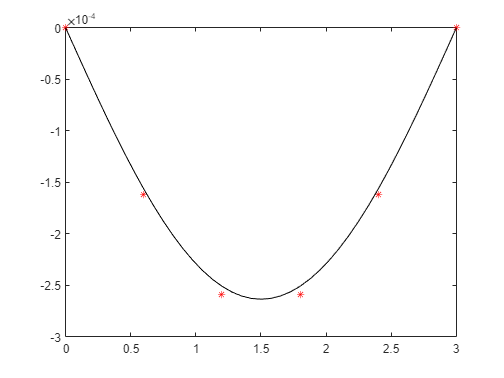

Y_FDM = A\b;
Y_FDM = [y0; Y_FDM; yf];
figure()
plot(X_FDM, Y_FDM, "r*", x, y(:,1), "-k")

## **Review Q2 - Taylor Series**

f = @(x) log(x) + 2*x.^2;
f2 = 8.6931;
% Calc f(3.5), 2nd order

0th    $\frac{f\left(a\right)}{0!}*1=f\left(a\right)$

1st    $\frac{f^{\prime } \left(a\right)}{1!}\left(x-a\right)$

2nd    $\frac{{f^{\prime } }^{\prime } \left(a\right)}{2!}{\left(x-a\right)}^2$

df = @(x) 1/x + 4*x;
df2 = @(x) -1/x^2 + 4;

a = 2;  %known point
x = 3.5;%poin to approx

zeroth = f(a)

zeroth = 8.6931

first = zeroth + df(a)*(x-a)

first = 21.4431

second = first + df2(a)*(x-a)^2/factorial(2)

second = 25.6619

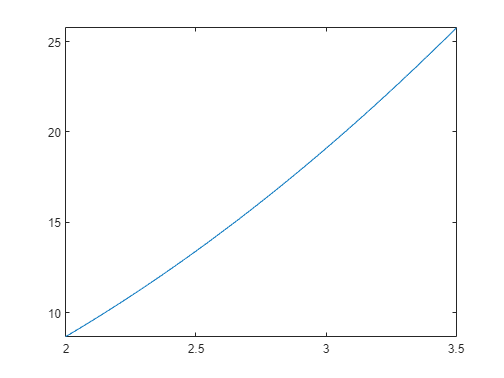

fplot(f, [a,x])

## **Review Q3- Romberg and Trapz**

f = @(x) exp(-x) + x.^2 + 6*x  -2;
a = 0;
b = 5;

h = 1;
n = (b-a)/h

n = 5

x = a:h:b;
int = 0;
for i = 1:n
    int = int + h/2*(f(x(i)) + f(x(i+1)));
end
I11 = int

I11 = 108.5747

h = h/2;
n = (b-a)/h

n = 10

x = a:h:b;
int = 0;
for i = 1:n
    int = int + h/2*(f(x(i)) + f(x(i+1)));
end
I12 = int

I12 = 107.8889

h = h/2;
n = (b-a)/h

n = 20

x = a:h:b;
int = 0;
for i = 1:n
    int = int + h/2*(f(x(i)) + f(x(i+1)));
end
I13 = int

I13 = 107.7172

I21 = 4/3*I12 - 1/3*I11

I21 = 107.6603

I22 = 4/3*I13 - 1/3*I12

I22 = 107.6600

I31 = 16/15*I22 - 1/15*I21

I31 = 107.6599